# `Clear Section`

clear
close all
clc

# `BPSK`

## Generate data bit stream

number_of_bits = 1000000;                % number of transmitted bits
amplitude = 1;                           % amp;itude of transmitted signal
bits = randi([0 1], 1, number_of_bits);  % generate random bits
Tx_Data = amplitude*(2*bits-1);          % converete to polar code

## Add AWGN from Channel

Eb = 1;                                              % energy of bit
SNR = -2:0.5:20;                                     % SNR valus 
No = Eb./(10.^(SNR/10));                             % variance value of noise
noise = (sqrt(No/2))'.*randn(1, number_of_bits);     % generate noise with zero mean and No/2 variance
var(noise(1, :));

## ِAdd Noise to Tx data

Rx_Data = Tx_Data + noise;                           % adding noise to Tx data

## BER Calculations

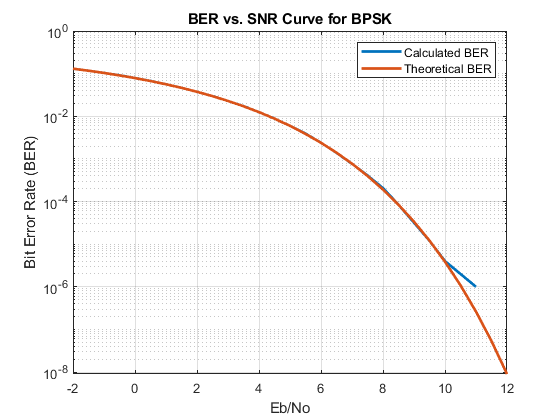

BER_Calculated_BPSK = zeros(1, length(SNR));
BER_Theoretical = 0.5*erfc(sqrt(Eb./No));
for i = 1 : length(SNR)
    BER_Calculated_BPSK(1, i) = (sum(sign(Rx_Data(i, :)) ~= Tx_Data))/number_of_bits;
end
semilogy(SNR, BER_Calculated_BPSK, 'LineWidth', 2)
xlim([-2 12])
hold on
semilogy(SNR, BER_Theoretical, 'LineWidth', 2)
xlabel("Eb/No")
ylabel("Bit Error Rate (BER)")
title("BER vs. SNR Curve for BPSK")
legend("Calculated BER", "Theoretical BER")
grid on
hold off

# `QPSK_1`

## Generate data bit stream

number_of_bits = 1000000;                % number of transmitted bits
M = 4;                                   % number of symbols
amplitude = 1;                           % amp;itude of transmitted signal
bits = randi([0 1], 1, number_of_bits);  % generate random bits
Data = amplitude*(2*bits-1);              % converete to polar code
real_part = Data(1, 1:2:end);            % get real part
imaginary = Data(1, 2:2:end);            % get imaginary part
Tx_Data = (real_part+1j*imaginary);       % determine Tx data

## Add AWGN from Channel

Eb = 1;                                              % energy of bit
SNR = -2:0.5:20;                                     % SNR values 
No = Eb./(10.^(SNR/10));                             % variance value of noise
noise = (sqrt(No/2))'.*randn(1, number_of_bits/2) + 1j*(sqrt(No/2))'.*randn(1, number_of_bits/2);    % generate noise with zero mean and No/2 variance

## Add Noise to Tx data

Rx_Data = Tx_Data + noise;                           % adding noise to Tx data

## BER Calculations

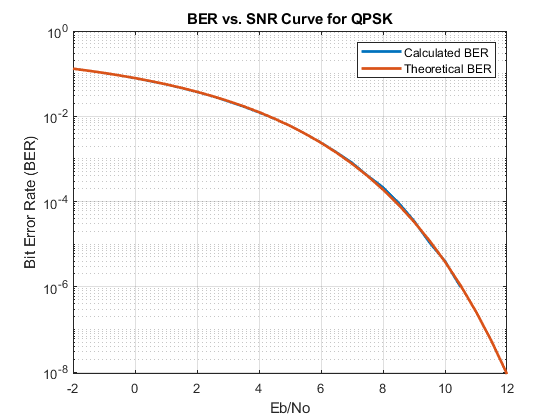

BER_Calculated_QPSK_1 = zeros(1, length(SNR));
BER_Theoretical_QPSK = 0.5*erfc(sqrt(Eb./No));
R = real(Rx_Data);
I = imag(Rx_Data);
extract_Data(1:size(R, 1), 1:2:2*size(R, 2)) = R;
extract_Data(1:size(I, 1), 2:2:2*size(I, 2)) = I;
for i = 1 : length(SNR)
    BER_Calculated_QPSK_1(1, i) = (sum(sign(extract_Data(i, :)) ~= Data))/number_of_bits;
end
semilogy(SNR, BER_Calculated_QPSK_1, 'LineWidth', 2)
xlim([-2 12])
hold on
semilogy(SNR, BER_Theoretical_QPSK, 'LineWidth', 2)
xlabel("Eb/No")
ylabel("Bit Error Rate (BER)")
title("BER vs. SNR Curve for QPSK")
legend("Calculated BER", "Theoretical BER")
grid on
hold off

## SER Calculations

SER_Calculated_QPSK = zeros(1, length(SNR));
%%%%%%%%%%%%%%%%%%%% Direct Calculation from BER %%%%%%%%%%%%%%%%%%%% 
% SER_Calculated_QPSK = 2*BER_Calculated_QPSK - BER_Calculated_QPSK.^2
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1 : length(SNR)
    SER_Calculated_QPSK(1, i) = sum(quadrant_number(Rx_Data(i, :)) ~= quadrant_number(Tx_Data))/(number_of_bits/log2(M));
end
SER_Calculated_QPSK;
BER_Calculated_QPSK_1;

# `QPSK_2`

## Generate data bit stream

Tx_Data = mapping_QPSK_2(Data);           % determine Tx data

## Add Noise to Tx data

Rx_Data = Tx_Data + noise;                 % adding noise to Tx data

## BER Calculations

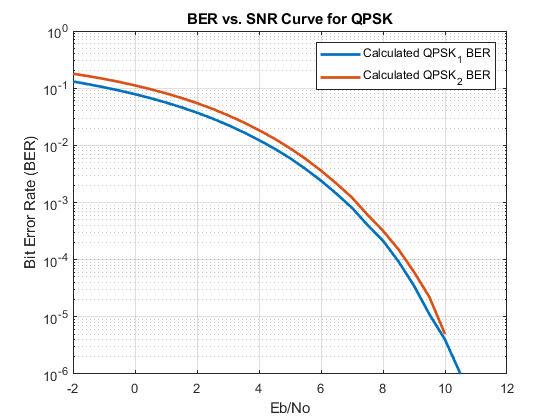

BER_Calculated_QPSK_2 = zeros(1, length(SNR));
for i = 1 : length(SNR)
    BER_Calculated_QPSK_2(1, i) = BER_QPSK_2(Data, Rx_Data(i, :))/number_of_bits;
end
semilogy(SNR, BER_Calculated_QPSK_1, 'LineWidth', 2)
xlim([-2 12])
hold on
semilogy(SNR, BER_Calculated_QPSK_2, 'LineWidth', 2)
% hold on
% semilogy(SNR, BER_Theoretical_QPSK, 'LineWidth', 2)
xlabel("Eb/No")
ylabel("Bit Error Rate (BER)")
title("BER vs. SNR Curve for QPSK")
legend("Calculated QPSK_1 BER", "Calculated QPSK_2 BER")
grid on
hold off

# `8PSK`

## Generate data bit stream

number_of_bits = 1000000-1;              % number of transmitted bits
M = 8;                                   % number of symbols
bits = randi([0 1], 1, number_of_bits);  % generate random bits
Tx_Data = mapping_8PSK(bits);            % determine Tx data

## Add AWGN from Channel

bits = log2(M);
Eb = 1;
E = Eb*bits;
SNR = -2:0.5:20;                                     % SNR values 
No = Eb./(10.^(SNR/10));                             % variance value of noise
noise = (sqrt(No/2))'.*randn(1, number_of_bits/bits) + 1j*(sqrt(No/2))'.*randn(1, number_of_bits/bits);    % generate noise with zero mean and No/2 variance

## Add Noise to Tx data

Rx_Data = Tx_Data + noise;                           % adding noise to Tx data

## BER Calculations

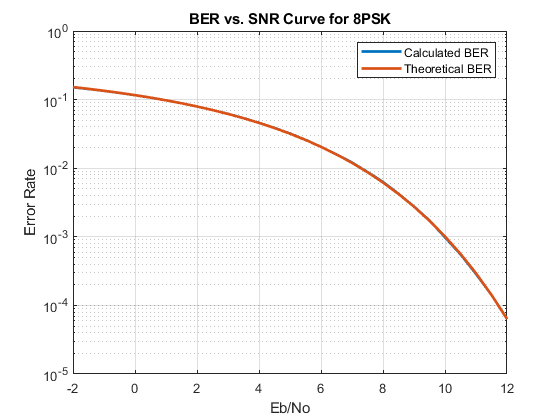

SER_Theoretical_8PSK = erfc(sqrt(E./No)*sin(pi/M));
SER_Calculated_8PSK = zeros(1, length(SNR));
for i = 1 : length(SNR)
    SER_Calculated_8PSK(1, i) = angle_8PSK(Tx_Data, Rx_Data(i, :))/(number_of_bits/log2(M));
end
BER_Calculated_8PSK = SER_Calculated_8PSK/bits; 
BER_Theoretical_8PSK = SER_Theoretical_8PSK/bits;
semilogy(SNR, BER_Calculated_8PSK, 'LineWidth', 2)
hold on
semilogy(SNR, BER_Theoretical_8PSK, 'LineWidth', 2)
xlim([-2 12])
xlabel("Eb/No")
ylabel("Error Rate")
title("BER vs. SNR Curve for 8PSK")
legend("Calculated BER", "Theoretical BER")
grid on
hold off

# `16QAM`

## Generate data bit stream

number_of_bits = 1000000;                    % number of transmitted bits
M = 16;                                      % number of symbols
amplitude = 1;                               % amp;itude of transmitted signal
data_bits = randi([0 1], 1, number_of_bits); % generate random bits
Tx_Data = mapping_16QAM(data_bits);          % determine Tx data

## Add AWGN from Channel

bits = log2(M);
Eb = 2.5;
E = Eb*0.4;
SNR = -2:0.5:20;                                     % SNR values 
No = Eb./(10.^(SNR/10));                             % variance value of noise
noise = (sqrt(No/2))'.*randn(1, number_of_bits/bits) + 1j*(sqrt(No/2))'.*randn(1, number_of_bits/bits);    % generate noise with zero mean and No/2 variance

## Add Noise to Tx data

Rx_Data = Tx_Data + noise;                           % adding noise to Tx data

## BER Calculations

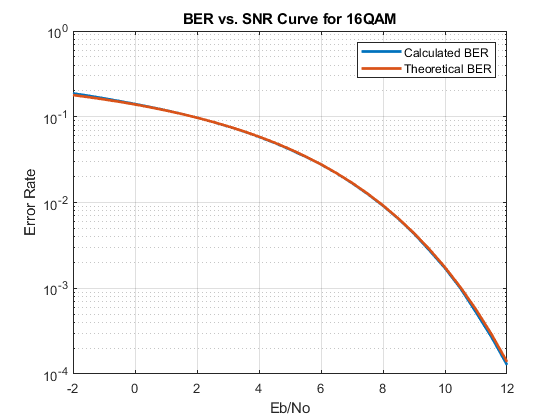

SER_Theoretical_16QAM = 1.5*erfc(sqrt(E./No));
BER_Calculated_16QAM = zeros(1, length(SNR));
for i = 1 : length(SNR)
    BER_Calculated_16QAM(1, i) = BER_16QAM(data_bits, Rx_Data(i, :))/(number_of_bits);
end
BER_Theoretical_16QAM = SER_Theoretical_16QAM/bits;
semilogy(SNR, BER_Calculated_16QAM, 'LineWidth', 2)
hold on
semilogy(SNR, BER_Theoretical_16QAM, 'LineWidth', 2)
xlim([-2 12])
xlabel("Eb/No")
ylabel("Error Rate")
title("BER vs. SNR Curve for 16QAM")
legend("Calculated BER", "Theoretical BER")
grid on
hold off

# `FSK`

## Generate data bit stream

number_of_bits = 1000000;                      % number of transmitted bits
amplitude = 1;                               % amp;itude of transmitted signal
data_bits = randi([0 1], 1, number_of_bits) % generate random bits

data_bits =      0     0     0     1     0     1     1     0     0     0     1     1     1     0     0     0     1     1     0     0     1     0     1     0     0     1     0     0     1     1     0     1     0     1     1     1     0     1     1     0     0     0     1     0     0     1     0     1     1     0


Tx_Data = data_bits;                          % determine Tx data
Tx_Data(Tx_Data==1)=1j

Tx_Data =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i


Tx_Data(Tx_Data==0)=1

Tx_Data =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i


## Add AWGN from Channel

Eb = 1;
SNR = -2:0.5:20;                                     % SNR values 
No = Eb./(10.^(SNR/10));                             % variance value of noise
noise = (sqrt(No/2))'.*randn(1, number_of_bits) + 1j*(sqrt(No/2))'.*randn(1, number_of_bits);    % generate noise with zero mean and No/2 variance

## Add Noise to Tx data

Rx_Data = Tx_Data + noise;                           % adding noise to Tx data

## BER Calculations

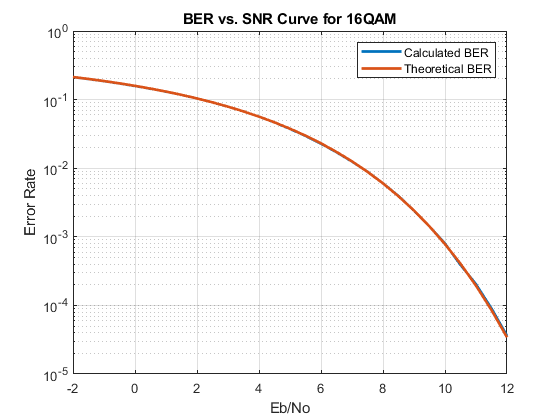

BER_Theoretical_FSK = 0.5*erfc(sqrt(E./(2*No)));
BER_Calculated_FSK = zeros(1, length(SNR));
for i = 1 : length(SNR)
    BER_Calculated_FSK(1, i) = BER_FSK(data_bits, Rx_Data(i, :))/(number_of_bits);
end
semilogy(SNR, BER_Calculated_FSK, 'LineWidth', 2)
hold on
semilogy(SNR, BER_Theoretical_FSK, 'LineWidth', 2)
xlim([-2 12])
xlabel("Eb/No")
ylabel("Error Rate")
title("BER vs. SNR Curve for 16QAM")
legend("Calculated BER", "Theoretical BER")
grid on
hold off

# `Comparison`

BER_Calculated_BPSK

BER_Calculated_BPSK =     0.1306    0.1172    0.1041    0.0913    0.0789    0.0673    0.0564    0.0464    0.0375    0.0297    0.0228    0.0173    0.0125    0.0088    0.0059    0.0039    0.0024    0.0014    0.0008    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


BER_Calculated_QPSK_1

BER_Calculated_QPSK_1 =     0.1307    0.1171    0.1036    0.0908    0.0784    0.0668    0.0560    0.0462    0.0373    0.0294    0.0226    0.0169    0.0123    0.0088    0.0060    0.0039    0.0024    0.0014    0.0008    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


BER_Calculated_QPSK_2

BER_Calculated_QPSK_2 =     0.1792    0.1621    0.1450    0.1283    0.1118    0.0960    0.0812    0.0674    0.0548    0.0435    0.0336    0.0253    0.0184    0.0131    0.0089    0.0058    0.0036    0.0021    0.0012    0.0006    0.0003    0.0002    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


BER_Calculated_BPSK

BER_Calculated_BPSK =     0.1306    0.1172    0.1041    0.0913    0.0789    0.0673    0.0564    0.0464    0.0375    0.0297    0.0228    0.0173    0.0125    0.0088    0.0059    0.0039    0.0024    0.0014    0.0008    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


BER_Calculated_16QAM

BER_Calculated_16QAM =     0.1874    0.1755    0.1636    0.1521    0.1407    0.1297    0.1188    0.1081    0.0976    0.0872    0.0772    0.0676    0.0583    0.0496    0.0415    0.0342    0.0278    0.0220    0.0169    0.0126    0.0092    0.0064    0.0043    0.0028    0.0017    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0


BER_Calculated_FSK

BER_Calculated_FSK =     0.2128    0.1995    0.1858    0.1721    0.1581    0.1442    0.1307    0.1172    0.1039    0.0911    0.0788    0.0673    0.0565    0.0465    0.0374    0.0296    0.0228    0.0171    0.0125    0.0089    0.0060    0.0039    0.0024    0.0014    0.0008    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


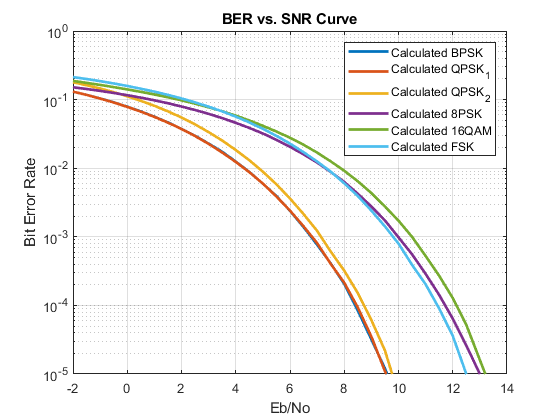

semilogy(SNR, BER_Calculated_BPSK, 'LineWidth', 2)
hold on
semilogy(SNR, BER_Calculated_QPSK_1, 'LineWidth', 2)
hold on
semilogy(SNR, BER_Calculated_QPSK_2, 'LineWidth', 2)
hold on
semilogy(SNR, BER_Calculated_8PSK, 'LineWidth', 2)
hold on
semilogy(SNR, BER_Calculated_16QAM, 'LineWidth', 2)
hold on
semilogy(SNR, BER_Calculated_FSK, 'LineWidth', 2)
xlabel("Eb/No")
ylabel("Bit Error Rate")
title("BER vs. SNR Curve")
ylim([10^-5 10^0])
legend("Calculated BPSK", "Calculated QPSK_1", "Calculated QPSK_2", "Calculated 8PSK", "Calculated 16QAM", "Calculated FSK")
grid on
hold off

# `Useful Functions    `

## `Determine quadrant number`

function y = quadrant_number(x)
    for i = 1 : length(x)
        if real(x(i)) > 0
            if imag(x(i)) > 0
                y(i) = 1;
            else
                y(i) = 4;
            end
        else
            if imag(x(i)) > 0
                y(i) = 2;
            else
                y(i) = 3;
            end
        end
    end
end

## `Mapping QPSK_2`

function y = mapping_QPSK_2(x)
    M = 4;
    bits = log2(M);
    Eb = 1;
    E = bits*Eb;
    split_x = reshape(x, bits, length(x)/bits)';
    y = size(length(split_x), 1);
    for i = 1:size(split_x, 1)
        if split_x(i, 1) == 1 && split_x(i, 2) == -1
            y(i)=sqrt(E/2)*(1+1j);
        end
        if split_x(i, 1) == -1 && split_x(i, 2) == 1
            y(i)=sqrt(E/2)*(-1+1j);
        end
        if split_x(i, 1) == -1 && split_x(i, 2) == -1
            y(i)=sqrt(E/2)*(-1-1j);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 1
            y(i)=sqrt(E/2)*(1-1j);
        end
    end
end

BER QPSK_2

function incorrect_bits = BER_QPSK_2(Tx_bits, Rx)
    M = 4;
    bits = log2(M);
    Rx_bits = zeros(1, bits*length(Rx));
    k = 1;
    for i = 1 : bits : length(Rx_bits)
        if (real(Rx(k)) >= 0)
            Rx_bits(i) = 1;
        else
            Rx_bits(i) = -1;
        end
        if (sign(real(Rx(k))) == sign(imag(Rx(k))))
            Rx_bits(i+1) = -1;
        else
            Rx_bits(i+1) = 1;
        end
        k = k + 1;
    end
    incorrect_bits = sum(Rx_bits ~= Tx_bits);
end

## `Mapping to 8PSK`

function y = mapping_8PSK(x)
    M = 8;
    bits = log2(M);
    Eb = 1;
    E = bits*Eb;
    split_x = reshape(x, bits, length(x)/bits)';
    y = size(length(split_x), 1);
    for i = 1:size(split_x, 1)
        if split_x(i, 1) == 0 && split_x(i, 2) == 0 && split_x(i, 3) == 0
            y(i)=sqrt(E)*exp(1j*0);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 0 && split_x(i, 3) == 1
            y(i)=sqrt(E)*exp(1j*pi/4);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 1 && split_x(i, 3) == 1
            y(i)=sqrt(E)*exp(1j*pi/2);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 1 && split_x(i, 3) == 0
            y(i)=sqrt(E)*exp(1j*3*pi/4);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 1 && split_x(i, 3) == 0
            y(i)=sqrt(E)*exp(1j*pi);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 1 && split_x(i, 3) == 1
            y(i)=sqrt(E)*exp(1j*5*pi/4);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 0 && split_x(i, 3) == 1
            y(i)=sqrt(E)*exp(1j*3*pi/2);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 0 && split_x(i, 3) == 0
            y(i)=sqrt(E)*exp(1j*7*pi/4);
        end
    end
end

## `Determine Angle of sympol in 8PSK number`

function incorrecr_bits = angle_8PSK(Tx, Rx)
    Tx_angles = rad2deg(mod(angle(Tx), 2*pi));   
    Rx_angles = rad2deg(mod(angle(Rx), 2*pi));
    Tx_sympols = zeros(1, length(Tx));
    Rx_sympols = zeros(1, length(Rx));
    for i = 1 : length(Tx_angles)
        if (Tx_angles(i) >= 0 && Tx_angles(i) < 22.5) || (Tx_angles(i) >= 337.5 && Tx_angles(i) < 360)
            Tx_sympols(i) = 1;
        end
        if (Tx_angles(i) >= 22.5 && Tx_angles(i) < 67.5)  
            Tx_sympols(i) = 2;
        end
        if (Tx_angles(i) >= 67.5 && Tx_angles(i) < 112.5)
            Tx_sympols(i) = 3;
        end
        if (Tx_angles(i) >= 112.5 && Tx_angles(i) < 157.5)
            Tx_sympols(i) = 4;
        end
        if (Tx_angles(i) >= 157.5 && Tx_angles(i) < 202.5)
            Tx_sympols(i) = 5;
        end
        if (Tx_angles(i) >= 202.5 && Tx_angles(i) < 247.5)
            Tx_sympols(i) = 6;
        end
        if (Tx_angles(i) >= 247.5 && Tx_angles(i) < 292.5)
            Tx_sympols(i) = 7;
        end
        if (Tx_angles(i) >= 292.5 && Tx_angles(i) < 337.5)
            Tx_sympols(i) = 8;
        end        
    end

    for i = 1 : length(Rx_angles)
        if (Rx_angles(i) >= 0 && Rx_angles(i) < 22.5) || (Rx_angles(i) >= 337.5 && Rx_angles(i) < 360)
            Rx_sympols(i) = 1;
        end
        if (Rx_angles(i) >= 22.5 && Rx_angles(i) < 67.5)  
            Rx_sympols(i) = 2;
        end
        if (Rx_angles(i) >= 67.5 && Rx_angles(i) < 112.5)
            Rx_sympols(i) = 3;
        end
        if (Rx_angles(i) >= 112.5 && Rx_angles(i) < 157.5)
            Rx_sympols(i) = 4;
        end
        if (Rx_angles(i) >= 157.5 && Rx_angles(i) < 202.5)
            Rx_sympols(i) = 5;
        end
        if (Rx_angles(i) >= 202.5 && Rx_angles(i) < 247.5)
            Rx_sympols(i) = 6;
        end
        if (Rx_angles(i) >= 247.5 && Rx_angles(i) < 292.5)
            Rx_sympols(i) = 7;
        end
        if (Rx_angles(i) >= 292.5 && Rx_angles(i) < 337.5)
            Rx_sympols(i) = 8;
        end        
    end    
    incorrecr_bits = sum(Rx_sympols ~= Tx_sympols);
end

## `Mapping to 16QAM`

function y = mapping_16QAM(x)
    M = 16;
    bits = log2(M);
    Eb = 2.5; %1;
    E = 0.4*Eb;
    split_x = reshape(x, bits, length(x)/bits)';
    y = zeros(1, length(split_x));
    for i = 1:size(split_x, 1)
        if split_x(i, 1) == 1 && split_x(i, 2) == 0 && split_x(i, 3) == 1 && split_x(i, 4) == 0 
            y(i)=sqrt(E)*(3+3j);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 1 && split_x(i, 3) == 1 && split_x(i, 4) == 0
            y(i)=sqrt(E)*(1+3j);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 1 && split_x(i, 3) == 1 && split_x(i, 4) == 1
            y(i)=sqrt(E)*(1+1j);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 0 && split_x(i, 3) == 1 && split_x(i, 4) == 1
            y(i)=sqrt(E)*(3+1j);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 1 && split_x(i, 3) == 0 && split_x(i, 4) == 1
            y(i)=sqrt(E)*(1-1j);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 0 && split_x(i, 3) == 0 && split_x(i, 4) == 1
            y(i)=sqrt(E)*(3-1j);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 1 && split_x(i, 3) == 0 && split_x(i, 4) == 0
            y(i)=sqrt(E)*(1-3j);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 0 && split_x(i, 3) == 0 && split_x(i, 4) == 0
            y(i)=sqrt(E)*(3-3j);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 1 && split_x(i, 3) == 1 && split_x(i, 4) == 1
            y(i)=sqrt(E)*(-1+1j);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 0 && split_x(i, 3) == 1 && split_x(i, 4) == 0
            y(i)=sqrt(E)*(-3+3j);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 0 && split_x(i, 3) == 1 && split_x(i, 4) == 1
            y(i)=sqrt(E)*(-3+1j);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 1 && split_x(i, 3) == 1 && split_x(i, 4) == 0
            y(i)=sqrt(E)*(-1+3j);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 1 && split_x(i, 3) == 0 && split_x(i, 4) == 1
            y(i)=sqrt(E)*(-1-1j);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 1 && split_x(i, 3) == 0 && split_x(i, 4) == 0
            y(i)=sqrt(E)*(-1-3j);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 0 && split_x(i, 3) == 0 && split_x(i, 4) == 1
            y(i)=sqrt(E)*(-3-1j);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 0 && split_x(i, 3) == 0 && split_x(i, 4) == 0
            y(i)=sqrt(E)*(-3-3j);
        end        
    end
end

BER for 16QAM

function incorrect_bits = BER_16QAM(Tx_bits, Rx)
    M = 16;
    bits = log2(M);
    Rx_bits = zeros(1, bits*length(Rx));
    k=1;
    for i = 1 : bits : length(Rx_bits)
        if (real(Rx(k)) >= 0)
            Rx_bits(i) = 1;
        else 
            Rx_bits(i) = 0;
        end
        if (real(Rx(k)) >= -2 && real(Rx(k)) < 2)
            Rx_bits(i+1) = 1;
        else 
            Rx_bits(i+1) = 0;
        end
        if (imag(Rx(k)) >= 0)
            Rx_bits(i+2) = 1;
        else 
            Rx_bits(i+2) = 0;
        end        
        if (imag(Rx(k)) >= -2 && imag(Rx(k)) < 2)
            Rx_bits(i+3) = 1;
        else 
            Rx_bits(i+3) = 0;
        end        
        k=k+1;
    end
    incorrect_bits = sum(Rx_bits ~= Tx_bits);
end

## `BER FSK`

function incorrect_bits = BER_FSK(Tx_bits, Rx)
    x1 = real(Rx);
    x2 = imag(Rx);    
    y = x1 - x2;
    Rx_bits = 0.5*(1-sign(y));
    incorrect_bits = sum(Rx_bits ~= Tx_bits);
end